# BMS Simulink/Simscape Model

#### RIT EVT - MSD BMS Project 2025-26

### Model Parameters

clear; clc; close all
% Cell Parameters
AH = 25.9;                              % Cell capacity
cell_area = 0.083377;
T_vec   = [278, 293, 313];              % Vector of temperatures, T, (K)
SOC_vec = [0, .1, .25, .5, .75, .9, 1]; % Vector of state-of-charge values, SOC
R0_mat  = [.0117, .0085, .009; .011, .0085, .009;...
    .0114, .0087, .0092; .0107, .0082, .0088; .0107, .0083, .0091;...
    .0113, .0085, .0089; .0116, .0085, .0089];  % Terminal resistance, R0(SOC,T), (ohm)
R1_mat  = [.0109, .0029, .0013; .0069, .0024, .0012;...
    .0047, .0026, .0013; .0034, .0016, .001; .0033, .0023, .0014;...
    .0033, .0018, .0011; .0028, .0017, .0011];  % First polarization resistance, R1(SOC,T), (ohm)
V0_mat  = [3.49, 3.5, 3.51; 3.55, 3.57, 3.56; 3.62, 3.63, 3.64;...
    3.71, 3.71, 3.72; 3.91, 3.93, 3.94; 4.07, 4.08, 4.08;...
    4.19, 4.19, 4.19];                          % Open-circuit voltage, V0(SOC,T), (V)
tau1_mat = [20, 36, 39; 31, 45, 39; 109, 105, 61;...
    36, 29, 26; 59, 77, 67; 40, 33, 29; 25, 39, 33]; % First time constant, tau1(SOC,T), (s)
h_conv   = 200;      % Heat transfer coefficient (W/(K*m^2))

thermal_mass = 100;                     % Thermal mass (J/K)
TempConst = 293;
tempLim = 318; %[K]

% Generate a vector of 24 random values between 3.2 and 3.25
initialSOC = 0.5 + (0.05) * rand(1, 24);

% Balancing Parameters
BalThreshold = 0.005;   % Threshold for cell balancing (V)
vMax         = 4.1;     % Maximum cell voltage
Ts           = 1;       % Sample time
MaxPackVoltage = vMax*24;
balanceResis = 33;      % Resistance of the balance resistors [ohms]

chargeCurrent = 20; %[A]
dischargeCurrent = -4; %[A]
currentLim = 225;
SOClowLim = 0.2;

chargeType = 1;
currentSlope = 1;

stepTime = 0;
% Create legend labels
legendLabels = arrayfun(@(n) sprintf('Cell %d', n), 1:24, 'UniformOutput', false);

out33ohm = sim("BMS_model_balancing.slx");

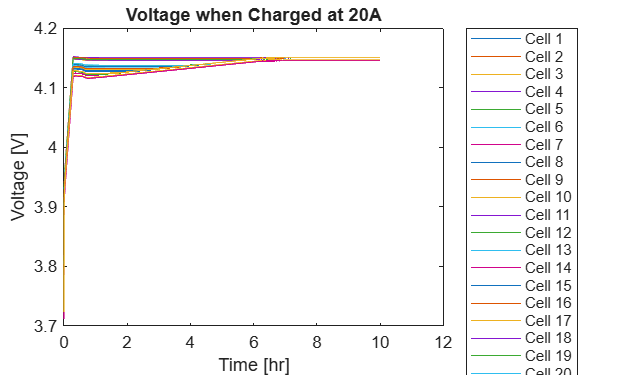

plot((1:Ts:length(out33ohm.cellV))/3600,out33ohm.cellV)
legend(legendLabels, 'Location', 'eastoutside')
xlabel('Time [hr]')
ylabel('Voltage [V]')
title('Voltage when Charged at 20A')

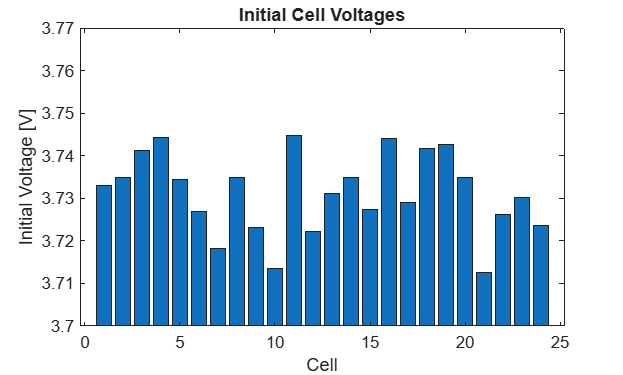


bar(1:1:24,out33ohm.cellV(1,:));
ylim([3.7,3.77])
xlabel('Cell')
ylabel('Initial Voltage [V]')
title('Initial Cell Voltages')

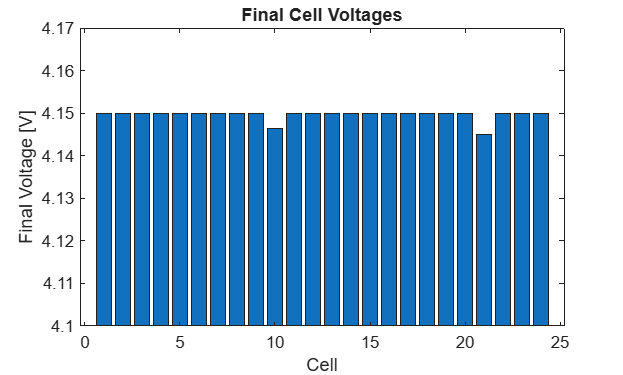


bar(1:1:24,out33ohm.cellV(end,:));
ylim([4.1,4.17])
xlabel('Cell')
ylabel('Final Voltage [V]')
title('Final Cell Voltages')


initialV = out33ohm.cellV(1,:);
finalV = out33ohm.cellV(end,:);
maxInitDiff = max(initialV)-min(initialV);
maxFinDiff = max(finalV)-min(finalV);
fprintf('Maximum Initial Voltage Difference: %0.4f V',maxInitDiff)

Maximum Initial Voltage Difference: 0.0323 V

fprintf('Maximum Final Voltage Difference: %0.4f V',maxFinDiff)

Maximum Final Voltage Difference: 0.0050 V

balanceResis = 10;
out10ohm = sim("BMS_model_balancing.slx");

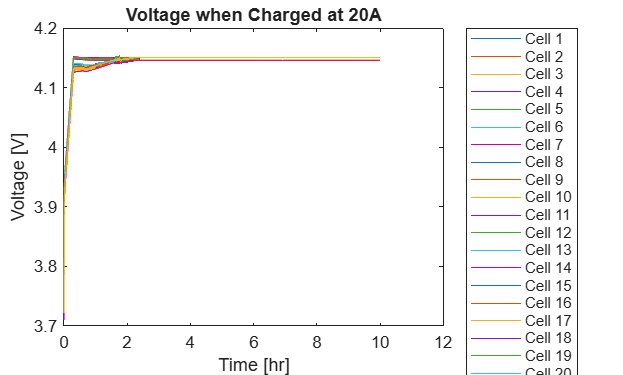

plot((1:Ts:length(out10ohm.cellV))/3600,out10ohm.cellV)
legend(legendLabels, 'Location', 'eastoutside')
xlabel('Time [hr]')
ylabel('Voltage [V]')
title('Voltage when Charged at 20A')

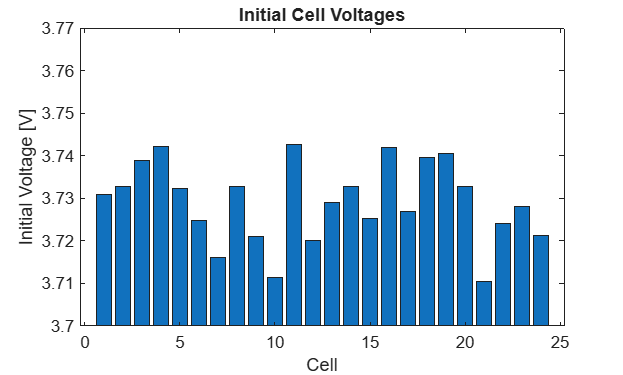


bar(1:1:24,out10ohm.cellV(1,:));
ylim([3.7,3.77])
xlabel('Cell')
ylabel('Initial Voltage [V]')
title('Initial Cell Voltages')


bar(1:1:24,out10ohm.cellV(end,:));
ylim([4.1,4.17])
xlabel('Cell')
ylabel('Final Voltage [V]')
title('Final Cell Voltages')


initialV = out10ohm.cellV(1,:);
finalV = out10ohm.cellV(end,:);
maxInitDiff = max(initialV)-min(initialV);
maxFinDiff = max(finalV)-min(finalV);
fprintf('Maximum Initial Voltage Difference: %0.4f V',maxInitDiff)

Maximum Initial Voltage Difference: 0.0323 V

fprintf('Maximum Final Voltage Difference: %0.4f V',maxFinDiff)

Maximum Final Voltage Difference: 0.0050 V

h_conv = 8;
outOverTemp = sim("BMS_model_balancing.slx");

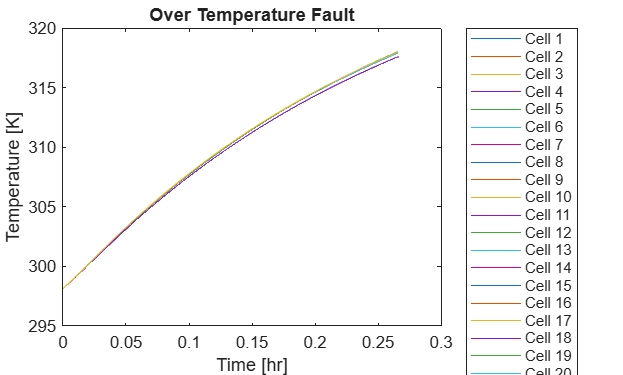

plot((1:Ts:length(outOverTemp.cellTemp))/3600,outOverTemp.cellTemp)
legend(legendLabels, 'Location', 'eastoutside')
xlabel('Time [hr]')
ylabel('Temperature [K]')
title('Over Temperature Fault')

h_conv = 200;
dischargeCurrent = -50;
stepTime = 10*3600;
outUnderSOC = sim("BMS_model_balancing.slx");

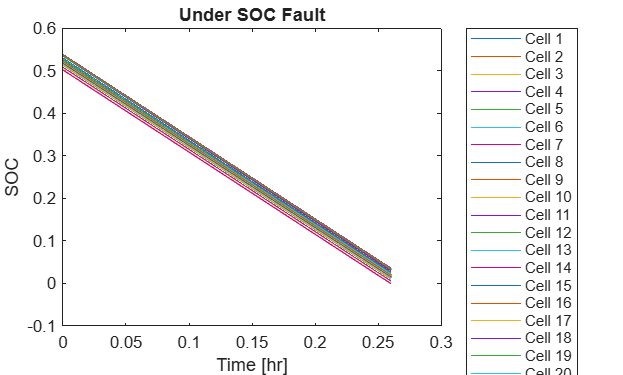

plot((1:Ts:length(outUnderSOC.cellSOC))/3600,outUnderSOC.cellSOC)
legend(legendLabels, 'Location', 'eastoutside')
xlabel('Time [hr]')
ylabel('SOC')
title('Under SOC Fault')

chargeCurrent = 40;
stepTime = 0;
chargeType = 2;
currentSlope = 0;
h_conv   = 1000;
outOverSOC = sim("BMS_model_balancing.slx");

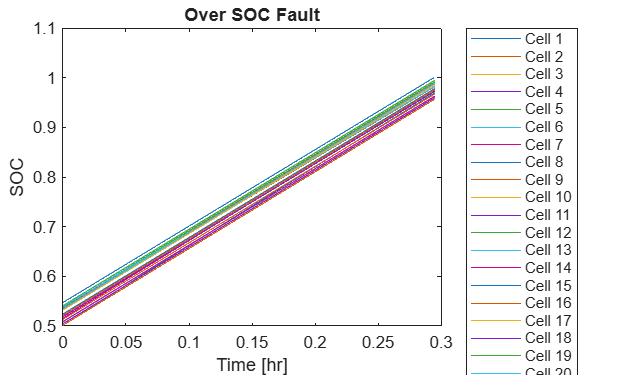

plot((1:Ts:length(outOverSOC.cellSOC))/3600,outOverSOC.cellSOC)
legend(legendLabels, 'Location', 'eastoutside')
xlabel('Time [hr]')
ylabel('SOC')
title('Over SOC Fault')

dischargeCurrent = 0;
currentSlope = 25;
outOverCurrent = sim("BMS_model_balancing.slx");

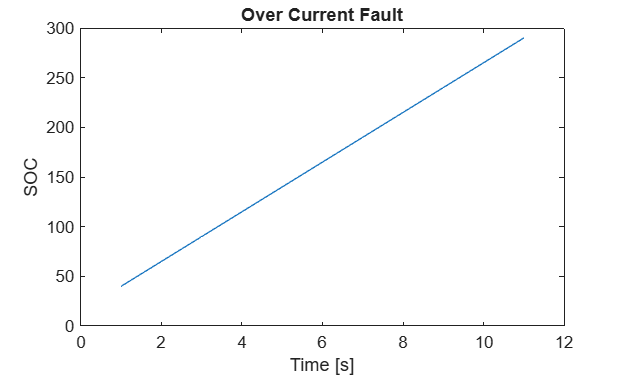

plot(outOverCurrent.current)
xlabel('Time [s]')
ylabel('SOC')
title('Over Current Fault')